clc;
clear;

%传递函数展示
num = [2 3 1];
den = [1 3 2];
sys = tf_zzy(num, den,0.1)


sys =

  2 z^2 + 3 z + 1
  ---------------
   z^2 + 3 z + 2

采样时间: 0.1 seconds
离散时间传递函数 (tf_zzy)。
模型属性



%  matlab

%新增了对象下标访问属性
sys.num

ans = 1×1 cell 数组
    {[2 3 1]}


%状态空间方程展示
clc;
clear;
A = [-1 0; 1 -2];
B = [1; 0];
C = [1 1];
D = 0;

% 创建离散时间系统

sys = ss_zzy(A, B, C, D, 0.1)


sys =

  A =
              x1       x2
    x1         -1         0
    x2          1        -2

  B =
              u1
    x1          1
    x2          0

  C =
              x1       x2
    y1          1         1

  D =
              u1
    y1          0

离散时间状态空间模型 (ss_zzy, Ts = 0.1)。
模型属性



%新增了对象下标访问属性
sys.A

ans =     -1     0
     1    -2


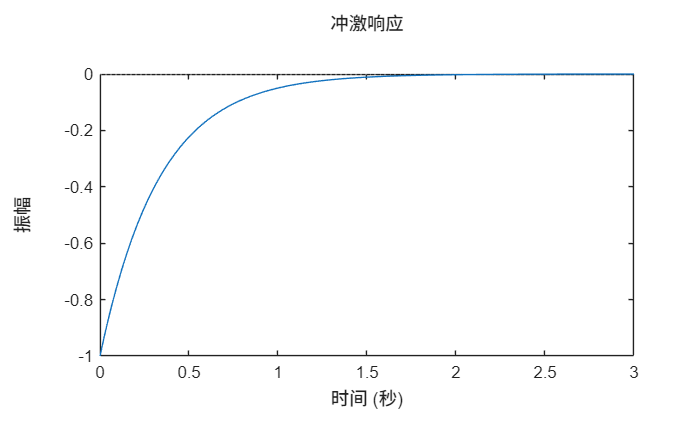

%冲激函数测试
clc;clear;
sys = tf([1 3 2], [1 4 3]);
impulse(sys,3);

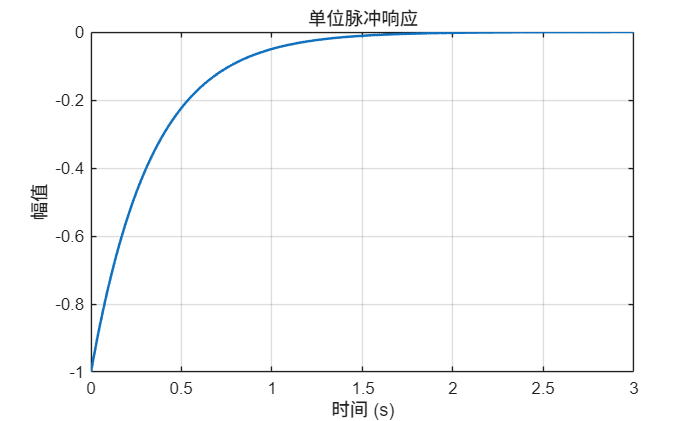


sys = tf_zzy([1 3 2], [1 4 3]);
impulse_zzy(sys,3);